Dumped Pendulum PID using LQR

% constants
a0 = -2;
a1 = 1;
b0 = 1;
r = 1; % contribution of control
% State space matreces
global A;

A = [0 1 0;
     0 0 1;
     0 -a0 -a1];
global B;

B = [0; 0; b0];
% LQR matreces
Q = eye(3);
R = r;

Solving algebraic Ricatti equation

global K;
[X1,K,L] = icare(A,B,Q,R);
K

K =     1.0000    5.4940    2.6039


Pendulum Simulation

% initial conditions
x10 = 0; % integral term zero at the beginning
x20 = 0.2; % phi
x30 = -0.6; % dphi
[t,x] = ode45(@(t,y) RHS(t, y, 'Control', true), [0 30], [x10 x20 x30]); % x = [INTphi phi dphi] state-space vector

Plotting

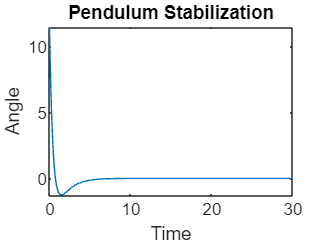


figure
plot(t, rad2deg(x(:,2)))
xlabel("Time")
ylabel("Angle")
title("Pendulum Stabilization")

function rhs = RHS(t, x, varargin)
    % default parameters
	p = inputParser; 
    p.addParameter('Control', true)
	p.parse(varargin{:});
    control = p.Results.Control;
    global A;
    global B;
    global K;
    if control == true
        v = -K*x; % full-state feedback
    else
        v = 0;
    end
    rhs = A*x + B.*v;
end